%% Project 1: Simulated Catapult Optimization

%  This script provides a complete solution for simulating and optimizing 
%  the performance of a virtual adjustable catapult. It calculates the 
%  projectile's trajectory using physics principles such as conservation 
%  of energy and projectile motion. The program evaluates different launch 
%  configurations to achieve the highest accuracy for hitting a target 
%  range of 10 feet (3.05 m).

%  Key tasks:
%   - Setting up initial simulation parameters (Part 1)
%   - Optimizing the launch angle and spring compression (Part 2)
%   - Visualizing trajectories and personalizing the launcher (Part 3)

% Clear memory
clear
% Clear Command Window
clc
% close all figures
close all

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Part 1: Setting up the Simulation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Define constants and initial parameters
R_target = 10.0*0.3048; % Target range in meters (converted from ft)
m = 0.045; % Projectile mass in kg
k = 5.1 * 175.12677; % Spring constant in N/m (converted from lb/in)
g = 9.81; % Gravity in m/s^2

s_min = 0.0381; % Minimum spring compression in meters (1.5 inches)
s_max = 0.0508; % Maximum spring compression in meters (2 inches)
theta_min = 15; % Minimum launch angle in degrees
theta_max = 75; % Maximum launch angle in degrees

s_comp = 1.8*0.0254;  % spring compression in meters (converted from in)

% Example preliminary inputs for simulation
s = s_comp; % Initial spring compression
theta_d = 45; % Launch angle in degrees
theta = theta_d*0.0174533; % Launch angle in radians

% Calculate launch velocity using conservation of energy
v0 = sqrt((k * s^2) / m);

% Time of flight, maximum height, and range calculations
t_flight = 2 * v0 * sin(theta) / g;
h_max = (v0^2 * sin(theta)^2) / (2 * g);
R_simulated = (v0^2 * sin(2 * theta)) / g;

% Time vector for trajectory calculation
t = linspace(0, t_flight, 100);

% Horizontal and vertical distance calculations
x = v0 * cos(theta) * t; % Horizontal distance
y = v0 * sin(theta) * t - 0.5 * g * t.^2; % Vertical distance

% Deliverable Part1.a: Display results in the command window
fprintf('Launch Angle: %.2f degrees\n', theta_d);

Launch Angle: 45.00 degrees


fprintf('Spring Compression: %.4f m\n', s);

Spring Compression: 0.0457 m


fprintf('Launch Velocity: %.2f m/s\n', v0);

Launch Velocity: 6.44 m/s


fprintf('Time of Flight: %.2f seconds\n', t_flight);

Time of Flight: 0.93 seconds


fprintf('Maximum Height: %.2f m\n', h_max);

Maximum Height: 1.06 m


fprintf('Range: %.2f m\n', R_simulated);

Range: 4.23 m


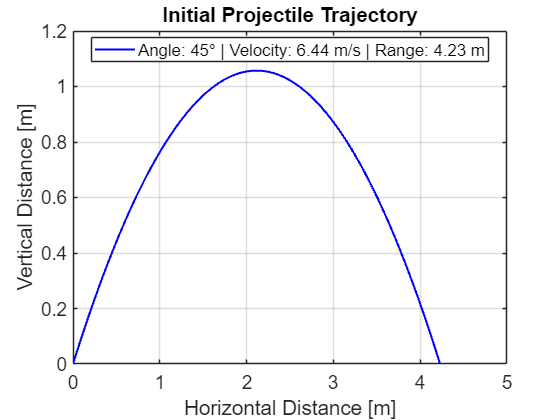


% Deliverable Part1.b: Plot the trajectory for visualization
figure;
plot(x, y, 'b-', 'LineWidth', 1.5);
xlabel('Horizontal Distance [m]');
ylabel('Vertical Distance [m]');
title('Initial Projectile Trajectory');
grid on;
% Add legend with calculated results
legendText = sprintf('Angle: %.0f° | Velocity: %.2f m/s | Range: %.2f m', theta_d, v0, R_simulated);
legend(legendText, 'Location', 'Best');
set(gca, 'Color', 'white'); % Axes background
set(gcf, 'Color', 'white'); % Figure background
set(gca, 'FontSize', 14); % Applies to all text within the axes

% print('P1b_Plot', '-dpng', '-r300');